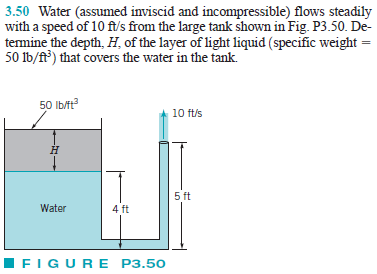

# given

u = symunit;
gamma_liquid = 50*u.lbf/u.ft^3;
gamma_water = 62.4*u.lbf/u.ft^3;
rho_water = 1.94*u.slug/u.ft^3;

# liquid (state 1)

H = sym('H');
p1_liquid = 0;
V1_liquid = 0;
z1_liquid = 4*u.ft+H;

# liquid (state 2)

p2_liquid = sym('p2_liquid');
V2_liquid = sym('V2_liquid');
z2_liquid = 4*u.ft;

# water (state 1)

p1_water = sym('p1_water');
V1_water = 0;
z1_water = 4*u.ft;

# water (state 2)

p2_water = 0;
V2_water = 10*u.ft/u.s;
z2_water = 5*u.ft;

# Bernoulli's Equation for the liquid

eqn = sym.zeros(3,1);
eqn(1) = p1_liquid+gamma_liquid*z1_liquid == p2_liquid;

# Bernoulli's Equation for the water

eqn(2) = p1_water+gamma_water*z1_water == p2_water+rho_water*V2_water^2/2+gamma_water*z2_water;

# Pressure Condition

eqn(3) = p2_liquid == p1_water;

# solution

[H p2_liquid p1_water] = solve(eqn); %#ok